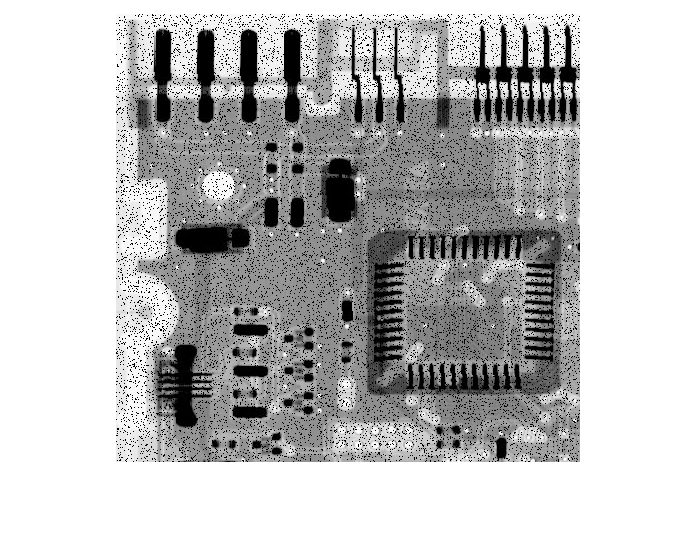

img_a = imread("../images/circuitboard-a.tif");
img_b = imread("../images/circuitboard-b.tif");
img_c = imread("../images/circuitboard-c.tif");
img_d = imread("../images/circuitboard-d.tif");
imshow(img_a)

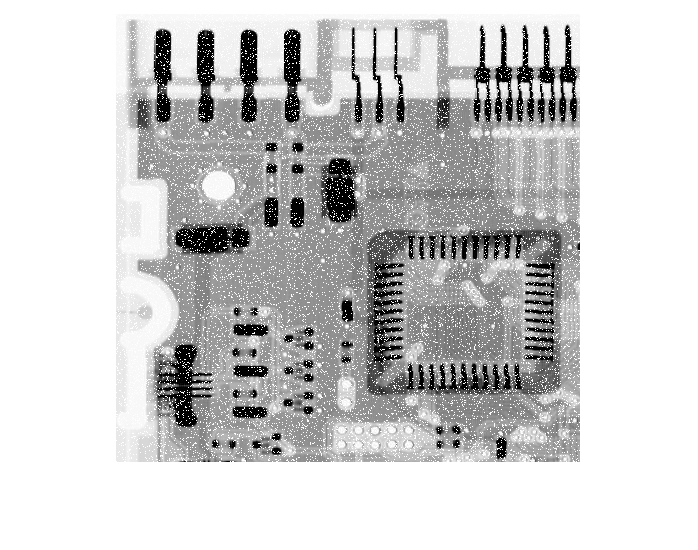

imshow(img_b)

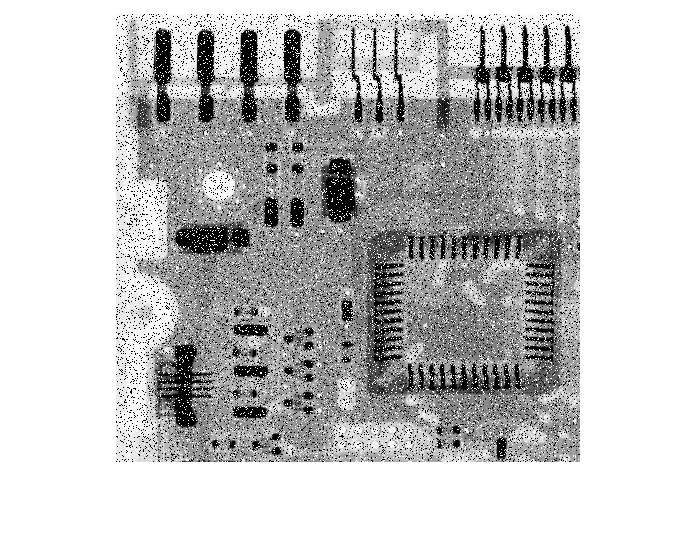

imshow(img_c)

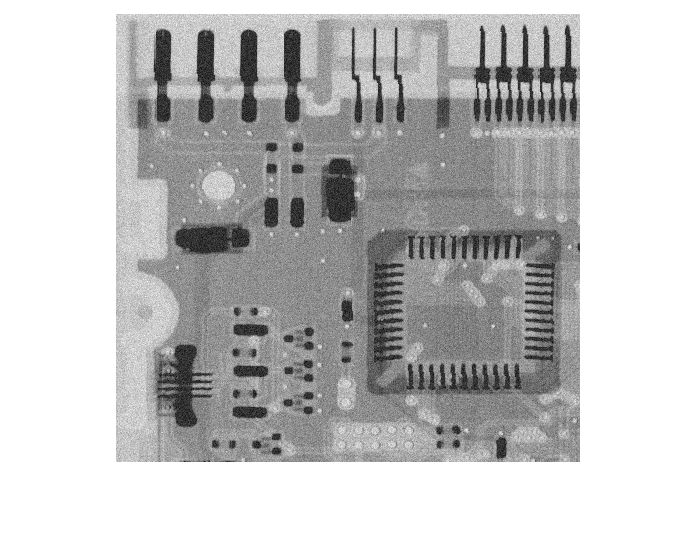

imshow(img_d)

[M, N] = size(img_a);

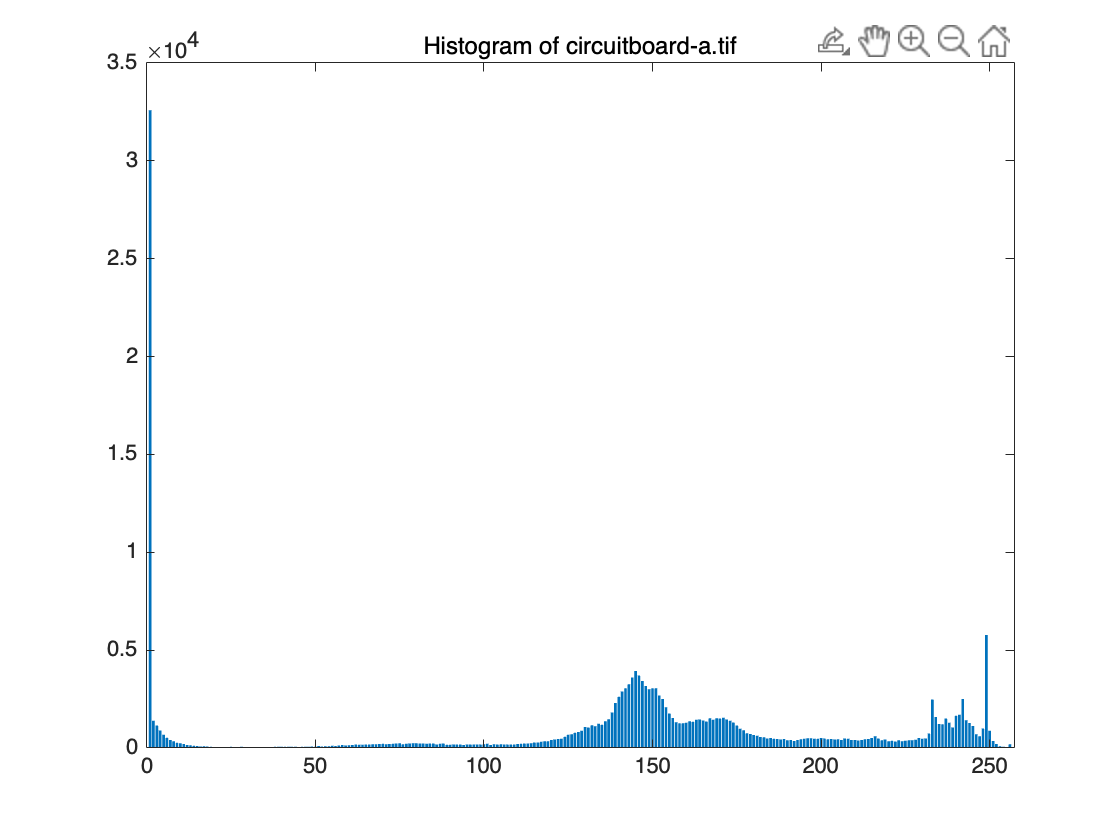

plotHistogram(img_a, "Histogram of circuitboard-a.tif")

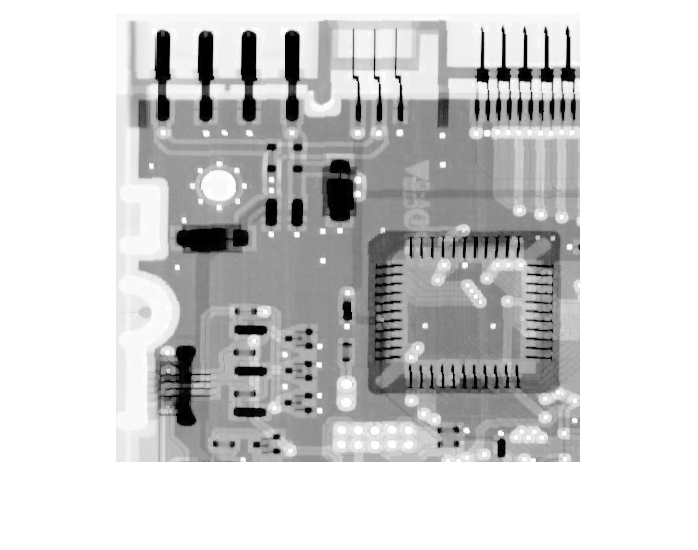

pad_a = padarray(img_a, [1, 1], "symmetric", "both");
res_a = zeros(size(img_a));
for i = 1:M
    for j = 1:N
%       using max filter 
        res_a(i,j) = max(max(pad_a(i:i+2, j:j+2)));
    end
end
imshow(uint8(res_a))

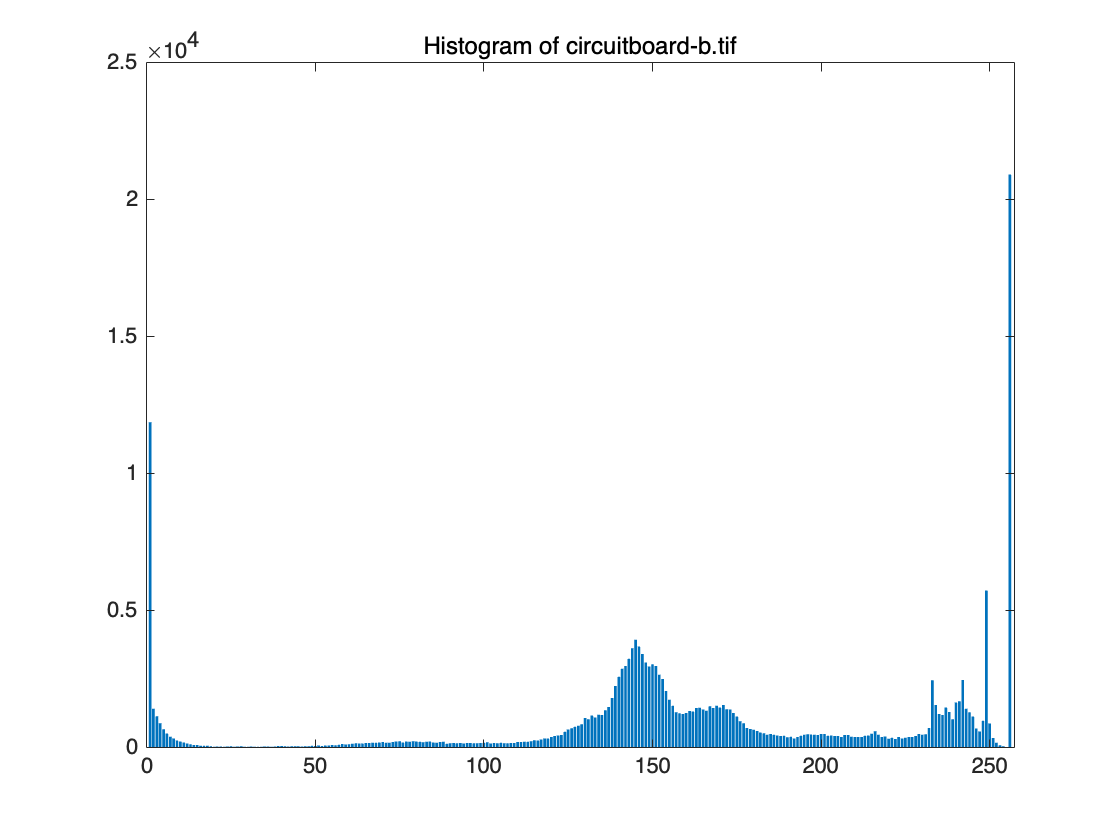

plotHistogram(img_b, "Histogram of circuitboard-b.tif")

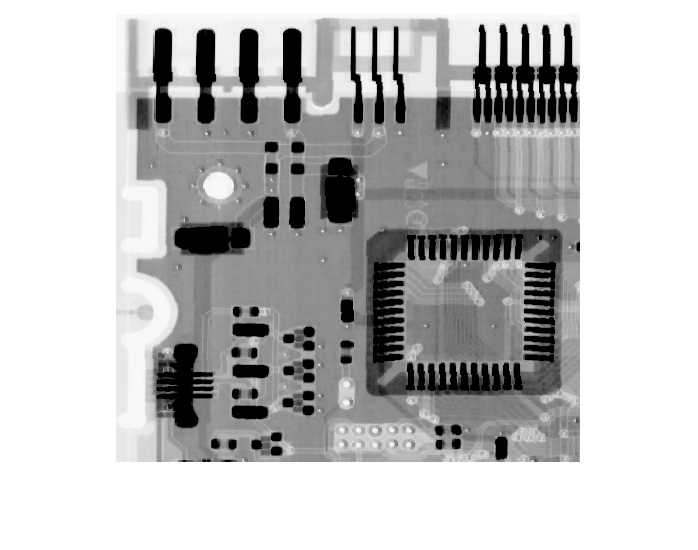

pad_b = padarray(img_b, [1, 1], "symmetric", "both");
res_b = zeros(size(img_b));
for i = 1:M
    for j = 1:N
%       using min filter
        res_b(i,j) = min(min(pad_b(i:i+2, j:j+2)));
    end
end
imshow(uint8(res_b))

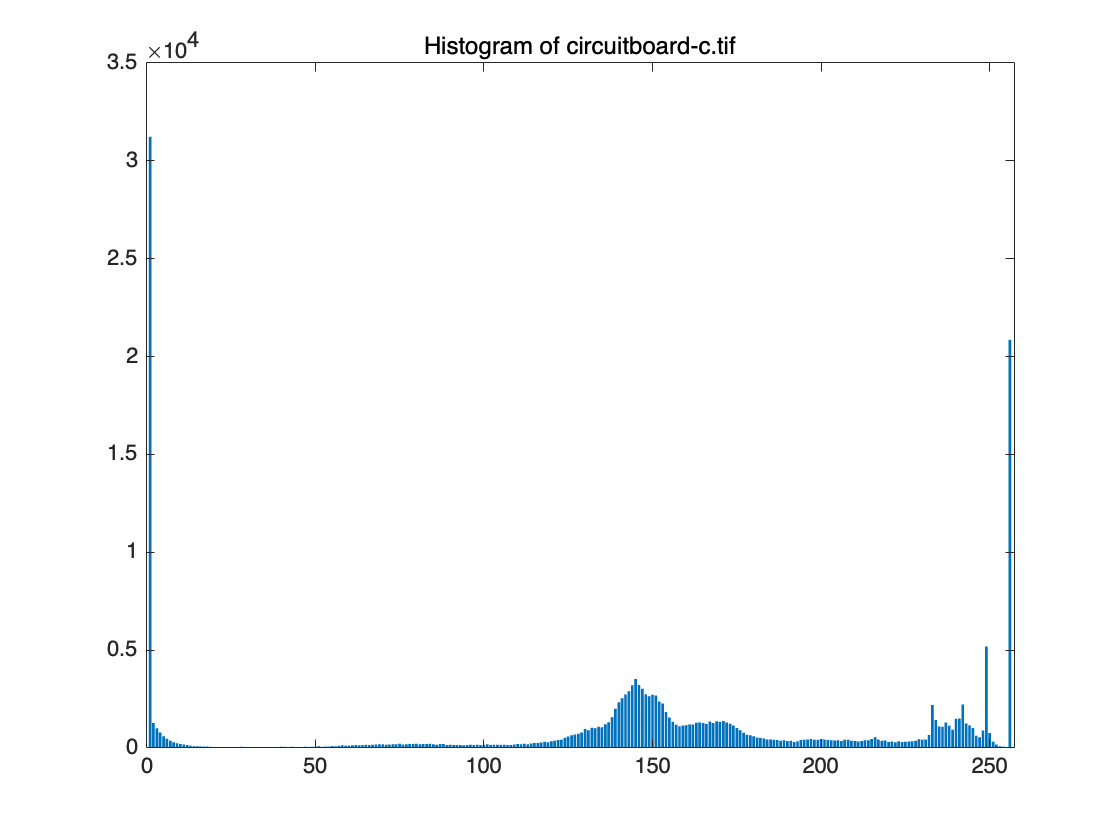

plotHistogram(img_c, "Histogram of circuitboard-c.tif")

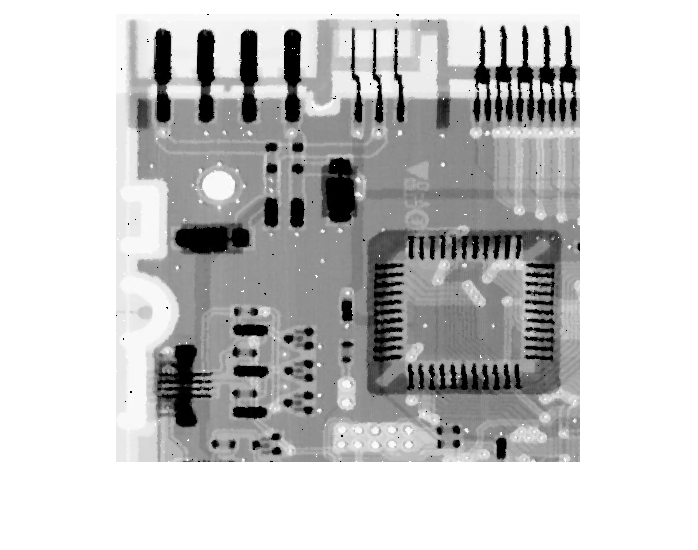

pad_c = padarray(img_c, [1, 1], "symmetric", "both");
res_c = zeros(size(img_c));
for i = 1:M
    for j = 1:N
%       using medain filter
        order = sort(reshape(pad_c(i:i+2, j:j+2), [9,1]));
        res_c(i,j) = order(5);
    end
end
imshow(uint8(res_c))

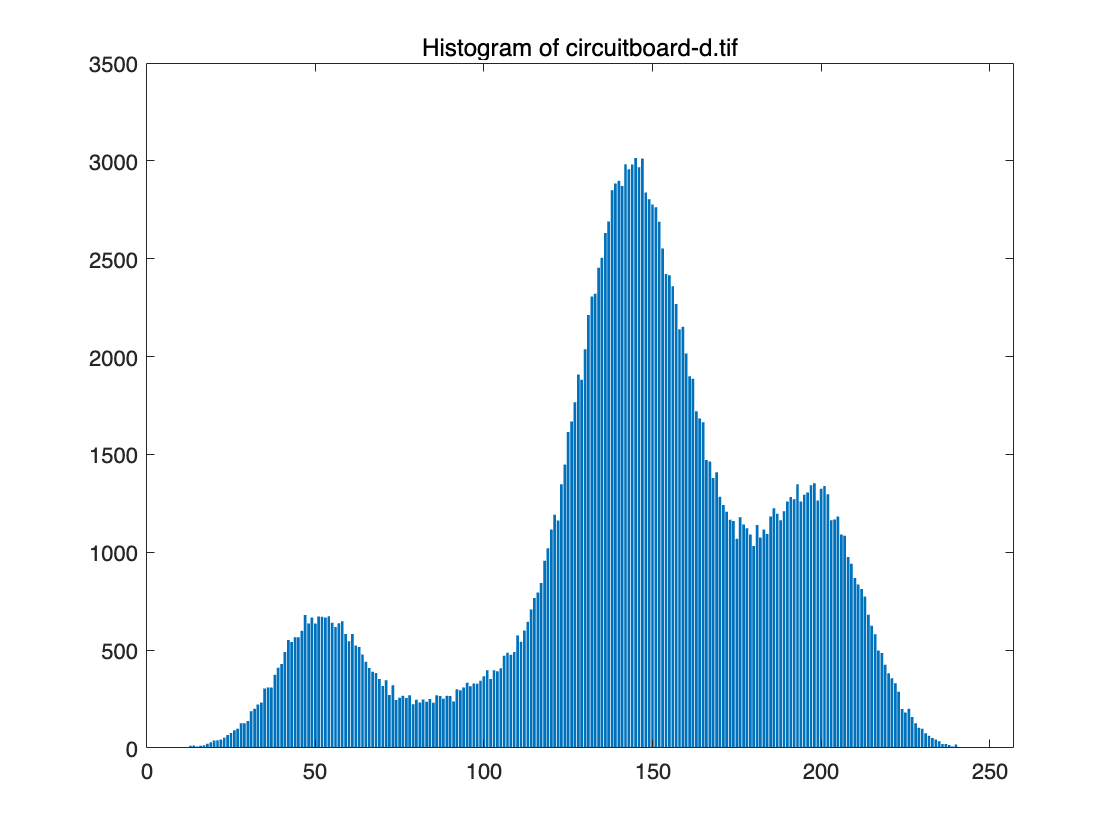

plotHistogram(img_d, "Histogram of circuitboard-d.tif")

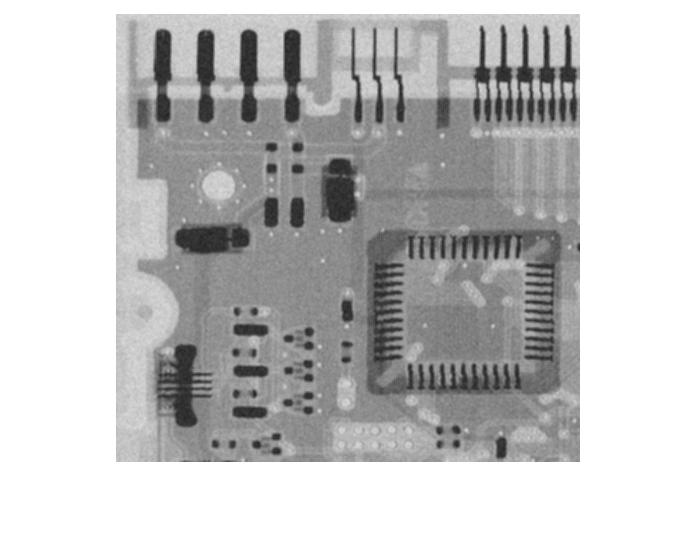

pad_d = padarray(img_d, [1, 1], "symmetric", "both");
res_d = zeros(size(img_d));
kernel = [1/9 1/9 1/9;
          1/9 1/9 1/9;
          1/9 1/9 1/9];

for i = 1:M
    for j = 1:N
%       use smooth filter
        res_d(i,j) = sum(sum(double(pad_d(i:i+2, j:j+2)) .* kernel));
    end
end
imshow(uint8(res_d))

function plotHistogram(image, image_title)
    hist = zeros(255, 1);
    for i = 0:255
        hist(i+1) = sum(sum(image == i));
    end
    figure;
    bar(hist);
    title(image_title);
end